# 3.3. Квазистационароное магнитное поле

#### Закон Ампера-Лапласа для магнитного поля витка с током


$$\mathit{\mathbf{B}}=\frac{\mu_0 I}{4\;\pi }\oint \frac{{\mathit{\mathbf{u}}}_T \times {\mathit{\mathbf{u}}}_r }{r^2 }\mathrm{dl}$$


clear
syms rot(x) grad(x) div(x) sprod(x,y) vprod(x,y)
syms B mu0 I u_T u_r r(L) L
B==mu0*I/(4*pi)*int(vprod(u_T,u_r)/r^2,L)

$$ans(L) = B=\frac{\text{I}\,\mu_{0}\,\int \frac{\mathrm{vprod}\left(u_{T},u_{r}\right)}{{r\left(L\right)}^{2}}\mathrm{d}L}{4\,\pi }$$

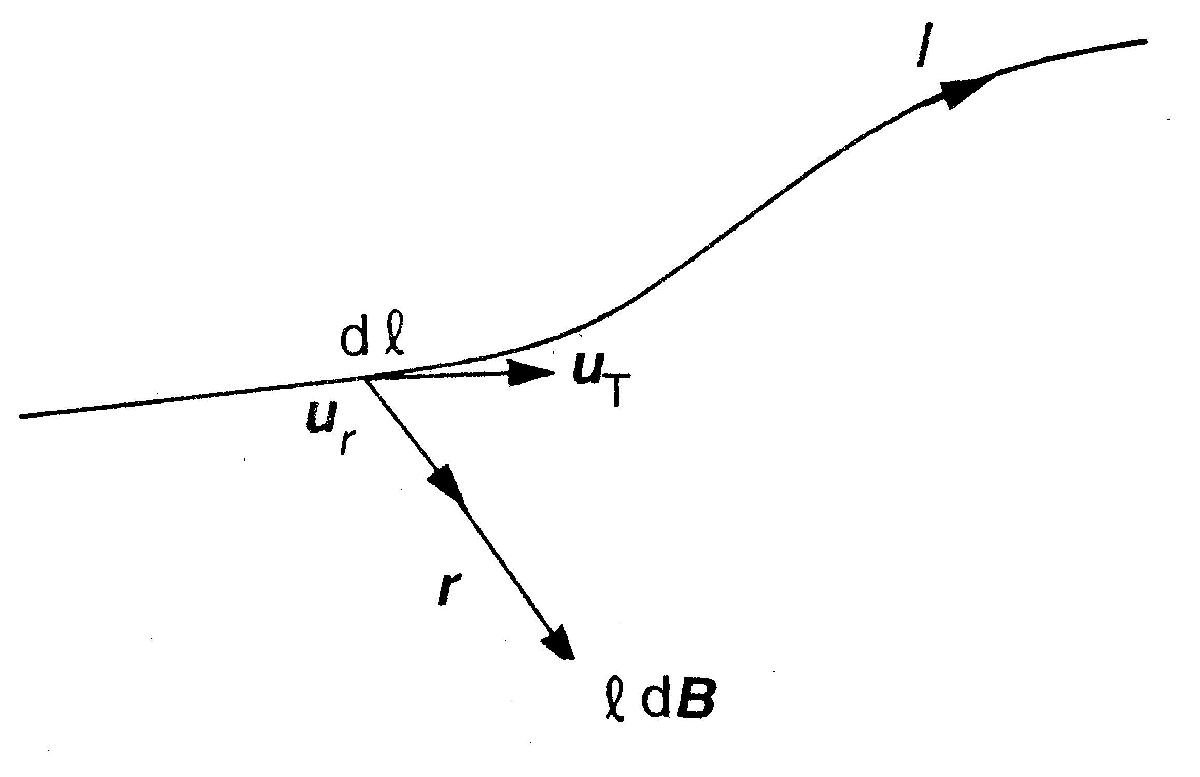


$$\mathit{\mathbf{dB}}=\frac{\mu_0 I}{4\;\pi }\frac{{\mathit{\mathbf{u}}}_T \times {\mathit{\mathbf{u}}}_r }{r^2 }\;\mathrm{dl}$$


syms dB dL r
dB==mu0*I/(4*pi)*(vprod(u_T,u_r)/r^2)*dL

$$ans = \mathrm{dB}=\frac{\text{I}\,\mathrm{dL}\,\mu_{0}\,\mathrm{vprod}\left(u_{T},u_{r}\right)}{4\,r^{2}\,\pi }$$

% u_T и u_r = единичные векторы

*Пример 1.* Поле на расстоянии d от длинного прямого проводника (формула Био-Савара) 

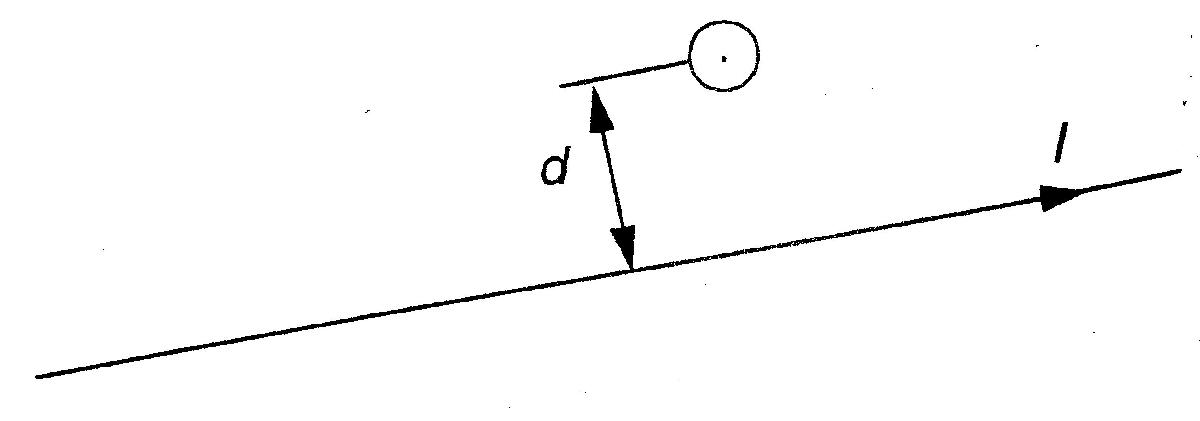

syms d
B==mu0/(4*pi)*(2*I/d)

$$ans = B=\frac{\text{I}\,\mu_{0}}{2\,d\,\pi }$$

*Пример 2.* Поле на оси круглого витка (короткий соленоид)

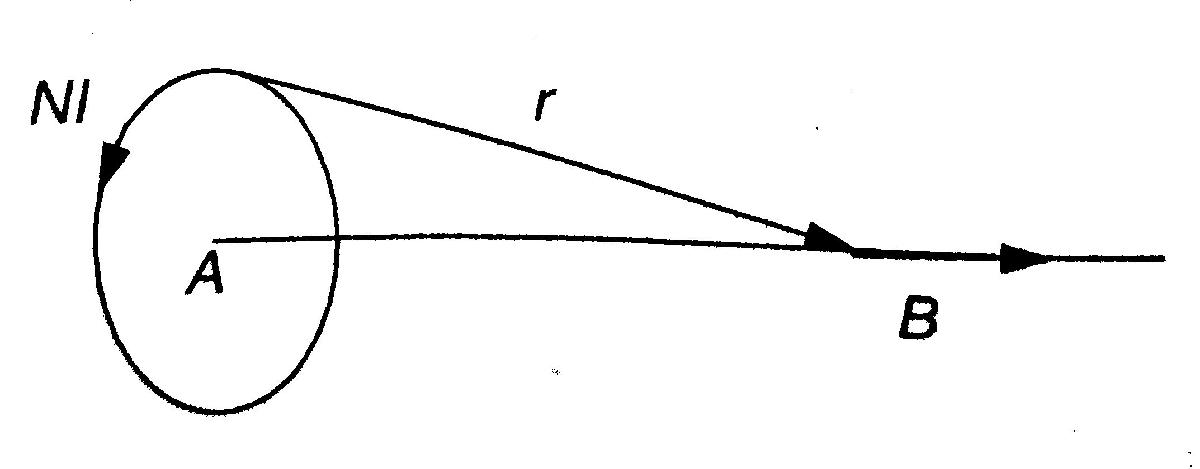

syms A N r mu0
B==mu0/(4*pi)*(2*N*I*A/r^3)

$$ans = B=\frac{A\,\text{I}\,N\,\mu_{0}}{2\,r^{3}\,\pi }$$

*Пример 3.* Поле на оси тонкого соленоида

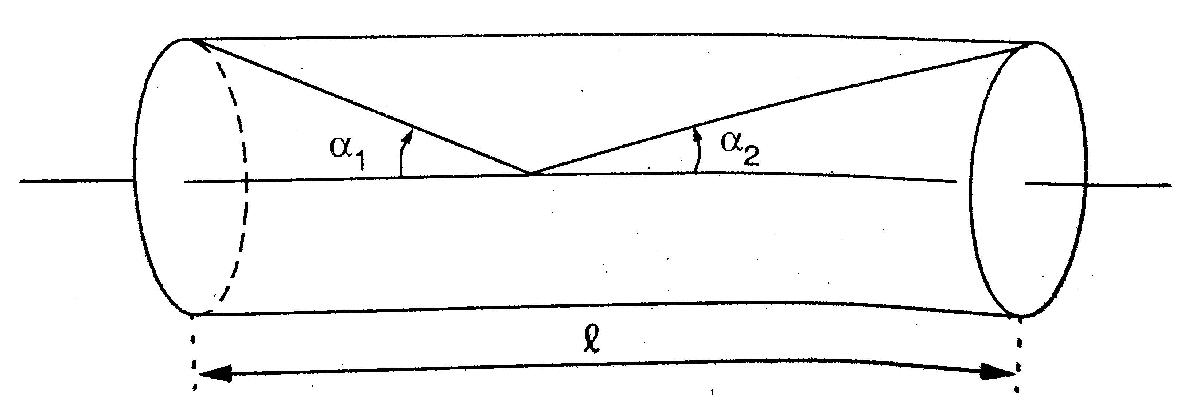

syms N I L alpha1 alpha2
B==mu0*(N*I/(2*L))*(cos(alpha1)+cos(alpha2))

$$ans = B=\frac{\text{I}\,N\,\mu_{0}\,\left(\cos\left(\alpha_{1}\right)+\cos\left(\alpha_{2}\right)\right)}{2\,L}$$

В частности, внутри длинного соленоида или тороидального соленоида

B==mu0*N*I/L

$$ans = B=\frac{\text{I}\,N\,\mu_{0}}{L}$$

*Пример 4.* Поле, создаваемое равномерно движущейся заряженной частицей


$$\mathit{\mathbf{B}}=\frac{\mu_0 }{4\;\pi }\frac{Q}{r^2 }\mathit{\mathbf{v}}\times {\mathit{\mathbf{u}}}_r$$


syms v u_r Q epsilon0 E 
B==mu0/(4*pi)*(Q/r^2)*vprod(v,u_r)

$$ans = B=\frac{Q\,\mu_{0}\,\mathrm{vprod}\left(v,u_{r}\right)}{4\,r^{2}\,\pi }$$


$$\mathit{\mathbf{B}}=\mu_0 \varepsilon_0 \;\mathit{\mathbf{v}}\times \mathit{\mathbf{E}}$$


syms v E
B==mu0*epsilon0*vprod(v,E)

$$ans = B=\epsilon_{0}\,\mu_{0}\,\mathrm{vprod}\left(v,\text{E}\right)$$

#### Закон Ампера (теорема о циркуляции)


$$\oint \mathit{\mathbf{B}}\;\mathit{\mathbf{dr}}=\mu_0 I$$


syms B(r)
int(B,r)==mu0*I

$$ans(r) = \int B\left(r\right)\mathrm{d}r=\text{I}\,\mu_{0}$$

syms H(r)


$$\oint \mathit{\mathbf{H}}\;\mathit{\mathbf{dr}}=I$$


int(H,r)==I

$$ans(r) = \int H\left(r\right)\mathrm{d}r=\text{I}$$


$$\mathrm{curl}\;\mathit{\mathbf{B}}=\mu_0 \mathit{\mathbf{j}}$$


syms B j
rot(B)==mu0*j

$$ans = \mathrm{rot}\left(B\right)=j\,\mu_{0}$$

% I = сила тока внутри замкнутого витка L

В частности, внутри проводника с однородной плотностью тока

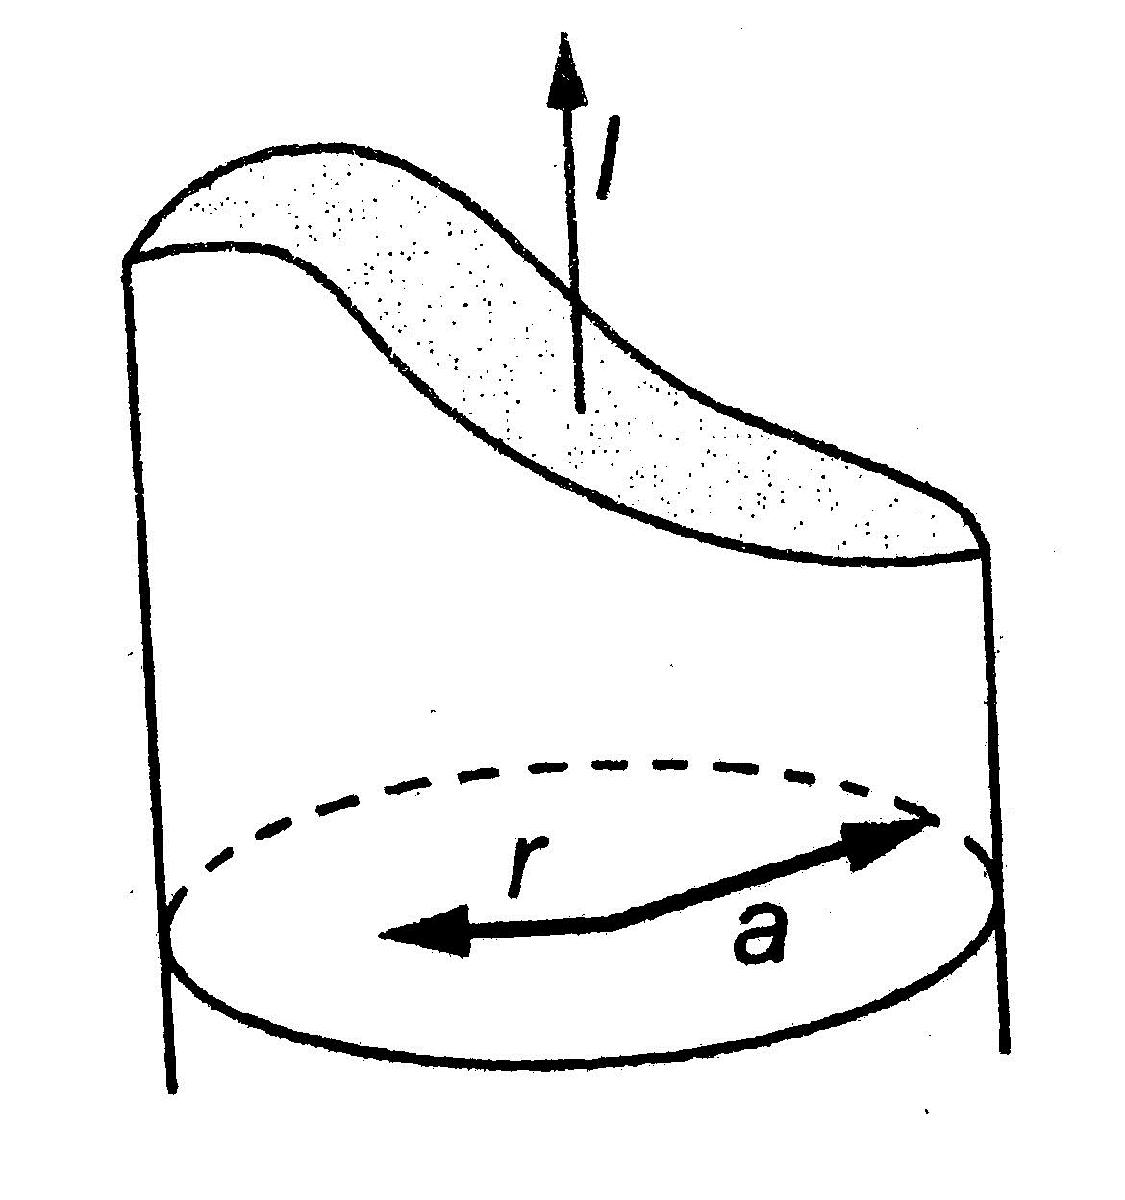

syms a B
B==mu0/(4*pi)*(2*r/a^2)*L

$$ans = B=\frac{L\,\mu_{0}\,r}{2\,a^{2}\,\pi }$$

#### Теорема Гаусса для магнитного поля


$$\Phi_B =\oint \mathit{\mathbf{B}}\;\mathit{\mathbf{dS}}=0$$


syms Phi_B B(S)
Phi_B==int(B,S)==0

$$ans(S) = \left(\Phi_{B}=\int B\left(S\right)\mathrm{d}S\right)=0$$


$$\mathrm{div}\;\mathit{\mathbf{B}}=0$$


syms B
div(B)==0

$$ans = \mathrm{div}\left(B\right)=0$$

#### Магнитный векторный потенциал A


$$\mathit{\mathbf{B}}=\mathrm{curl}\;\mathit{\mathbf{A}}$$


syms B A j(V)
B==rot(A) 

$$ans = B=\mathrm{rot}\left(A\right)$$


$$\mathit{\mathbf{A}}=\frac{\mu_0 }{4\;\pi }\int \frac{\mathit{\mathbf{j}}}{r}\;\mathit{dV}$$


A==mu0/(4*pi)*int(j/r,V)

$$ans(V) = A=\frac{\mu_{0}\,\int \frac{j\left(V\right)}{r}\mathrm{d}V}{4\,\pi }$$

В частности, для однородного магнитного поля


$$\mathit{\mathbf{A}}=\frac{1}{2}\mathit{\mathbf{B}}\times \mathit{\mathbf{r}}$$


syms B r
A==1/2*vprod(B,r)

$$ans = A=\frac{\mathrm{vprod}\left(B,r\right)}{2}$$

#### Магнитная сила, действующая на электрический проводник


$$\mathrm{dF}=B\;I\;\mathrm{sin}\;\theta \;\mathrm{dr}$$


syms dF B I theta dr
dF==B*I*sin(theta)*dr

$$ans = \mathrm{dF}=B\,\text{I}\,\mathrm{dr}\,\sin\left(\theta \right)$$


$$\mathit{\mathbf{dF}}=I\;\mathit{\mathbf{dr}}\times \mathit{\mathbf{B}}$$


syms dr B
dF==I*vprod(dr,B)

$$ans = \mathrm{dF}=\text{I}\,\mathrm{vprod}\left(\mathrm{dr},B\right)$$

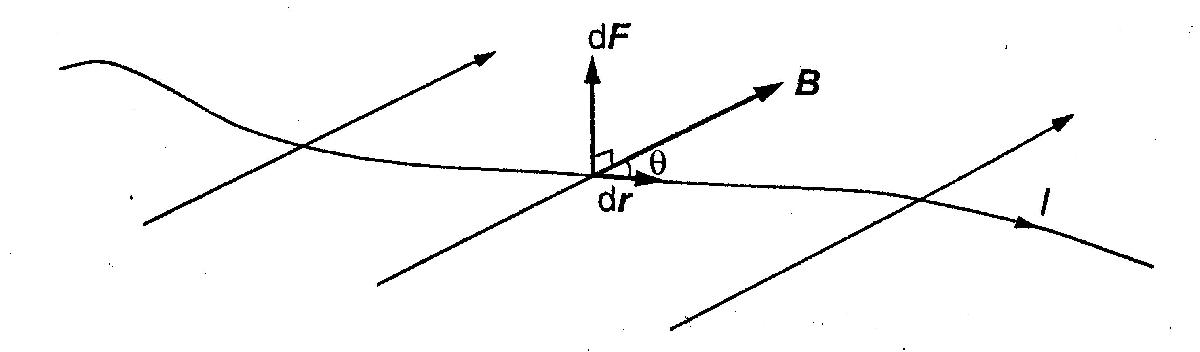

В частности, сила взаимодействия параллельных проводников, каждый длиной L

syms F L a I1 I2
F==mu0/(4*pi)*(2*L/a)*I1*I2

$$ans = F=\frac{I_{1}\,I_{2}\,L\,\mu_{0}}{2\,a\,\pi }$$